# Example: Uncertainty Quantification of a Differential Amplifier

Copyright (C) 2022 Miodrag Bolic

  This program is free software: you can redistribute it and/or modify   it under the terms of the GNU General Public License as published by  the Free Software Foundation, either version 3 of the License, or  (at your option) any later version.  This program is distributed in the hope that it will be useful, but WITHOUT ANY WARRANTY; without even the implied warranty of MERCHANTABILITY or FITNESS FOR A PARTICULAR PURPOSE.  See the GNU General Public License for more details <https://www.gnu.org/licenses/>. 

This code was developed by Miodrag Bolic for the book PERVASIVE CARDIAC AND RESPIRATORY MONITORING DEVICES

% Changing the path from main_folder to a particular chapter
main_path=fileparts(which('Main_Content.mlx'));
if ~isempty(main_path)
    %addpath(append(main_path,'/Chapter2'))
    cd (append(main_path,'/Chapter1/Uncertainty'))
    addpath(append(main_path,'/Service'))
end
SAVE_FLAG=0; % saving the figures in a file

## Introduction 

Resistors are commonly given with their tolerance of 0.1 %, 1 %, 2 % and so on. It is commonly assumed that the resistor values follow uniform distribution. If the tolerance is given as the variable (tol) then the values of the resistor can be sampled from the uniform distribution in the range  [R - tol , R + tol]. 

## Differential Amplifier 

The simulation of the Differential Amplifier circuit can be seen below. Differential amplifiers amplifies the difference between the input voltages. For the selected values of resistors, the output of this circuit is 10 times larger than the difference between inputs. Resistors have the following values : R1=10 kΩ, R2=100 kΩ, R3=10 kΩ and R4=100 kΩ. Tolerance of each resistor is 1%. For the input voltage difference of 0.2 V, the output is 2 V. 

## 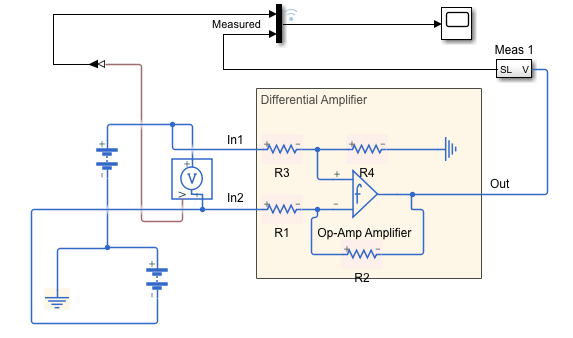                         

## Running Model

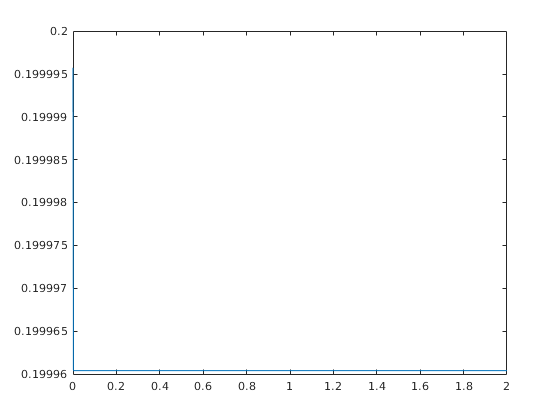

% Code to plot simulation results from Differential amplifier
% Running model for the first time
model_name = 'Diff_ampl1';
open_system(model_name);
sim(model_name)
plot(logsout_diff_amp{1}.Values.Time, logsout_diff_amp{1}.Values.Data(:,1))

### Making Resistor Labels Visible

find_system can find systems, blocks, lines, ports and returns the objects in the specified system that meet the specified criteria.

set_param will set system and block parameter values


SETTING_PARAM=0;
if SETTING_PARAM
    blockNames = find_system( model_name , 'Type' , 'Block' );
    for k = 1 : length( blockNames )
        set_param( blockNames{k} , 'ShowName' , 'on' );
    end;
    set_param('Diff_ampl1/ERef Diff Amp1' , 'ShowName' , 'off' );
    set_param('Diff_ampl1/ERef Diff Amp' , 'ShowName' , 'off' );
end

### Maximum tolerance test

Running tests and getting results for the simulation with maximum tolerance considered. 

% Get simulation results
% Max Tolerance
set_param('Diff_ampl1/R1','enable_R_tol','3');
set_param('Diff_ampl1/R2','enable_R_tol','2');
set_param('Diff_ampl1/R3','enable_R_tol','3');
set_param('Diff_ampl1/R4','enable_R_tol','2');
sim('Diff_ampl1');
simlog_prSensorMaxTol = logsout_diff_amp.get('Pr_Signal');

### Minimum tolerance test

Running tests and getting results for the simulation with minimum tolerance considered. 


% Get simulation results
% Min Tolerance
set_param('Diff_ampl1/R1','enable_R_tol','2');
set_param('Diff_ampl1/R2','enable_R_tol','3');
set_param('Diff_ampl1/R3','enable_R_tol','2');
set_param('Diff_ampl1/R4','enable_R_tol','3');
sim('Diff_ampl1');
simlog_prSensorMinTol = logsout_diff_amp.get('Pr_Signal');


### Random tolerance

Generate random values of resistors assuming that their values follow the uniform distribution. 

RANDOM_TOLERANCE=1

RANDOM_TOLERANCE = 1

ci =     1.9764    0.0148
    1.9780    0.0159


ci_percent =    -1.1793
   -1.0995


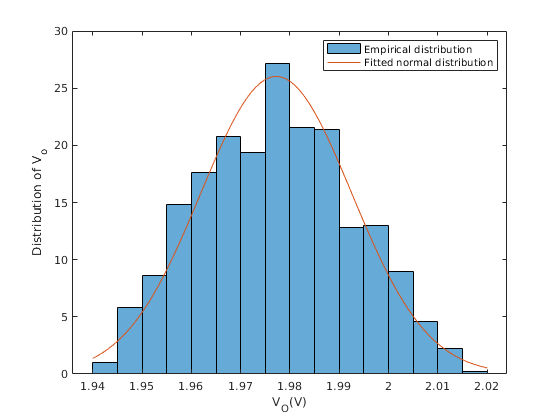

if RANDOM_TOLERANCE
    for i=1:1000
        set_param('Diff_ampl1/R1','enable_R_tol','1'); % random tolerance
        set_param('Diff_ampl1/R2','enable_R_tol','1');
        set_param('Diff_ampl1/R3','enable_R_tol','1');
        set_param('Diff_ampl1/R4','enable_R_tol','1');
        set_param('Diff_ampl1/R1','tol_distribution','1'); %1 is uniform, 2 is Gaussian
        set_param('Diff_ampl1/R2','tol_distribution','1');
        set_param('Diff_ampl1/R3','tol_distribution','1');
        set_param('Diff_ampl1/R4','tol_distribution','1');
        sim('Diff_ampl1');
        simlog_param=logsout_diff_amp.get('Pr_Signal');
        param_mean(i)=mean(simlog_param.Values.Data(10:end,2));
        
    end
    figure, histogram(param_mean,'Normalization','pdf')
    pd=fitdist(param_mean','Normal');
        z1=1.94:0.001:2.02;
        y=pdf(pd,z1);
        hold on
        plot(z1,y)
        ci=paramci(pd,0.1) %0.05
        ci_percent=100*(ci(:,1)-2)/2
    ylabel('Relative frequency of V_o')
    xlabel('V_O (V)');
    legend('Empirical distribution','Fitted normal distribution')
    title('The empirical distribution of V_o')
    annonation_save('',"Fig1.11.jpg", SAVE_FLAG);
end

% Nominal Value
set_param('Diff_ampl1/R1','enable_R_tol','0');
set_param('Diff_ampl1/R2','enable_R_tol','0');
set_param('Diff_ampl1/R3','enable_R_tol','0');
set_param('Diff_ampl1/R4','enable_R_tol','0');


### Results

Final results for the differential input, maximum tolerance, and minimum tolerance will be plotted. 

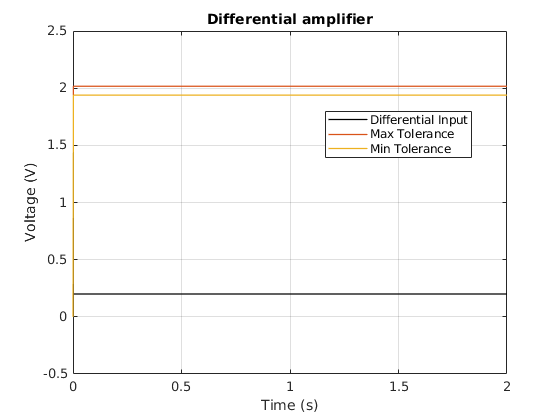

% Plot results
plot(simlog_prSensorMinTol.Values.Time, simlog_prSensorMinTol.Values.Data(:,1), 'k','LineWidth', 1)
hold on
plot(simlog_prSensorMaxTol.Values.Time, simlog_prSensorMaxTol.Values.Data(:,2), 'LineWidth', 1)
plot(simlog_prSensorMinTol.Values.Time, simlog_prSensorMinTol.Values.Data(:,2), 'LineWidth', 1)
hold off
grid on
title('Differential amplifier')
ylabel('Voltage (V)')
legend({'Differential Input', 'Max Tolerance','Min Tolerance'},'Location','Best');
xlabel('Time (s)');

## Uncertainty analysis 

`sdo.getParameterFromModel(modelname,paramname)` will creates an object from the Simulink model parameter that can be tuned to satisfy design requirements during optimization. 

R1 = sdo.getParameterFromModel(model_name, 'R1');
% R1.Minimum=R1.Value*1.01;
% R1.Maximum=R1.Value*0.99;

R2 = sdo.getParameterFromModel(model_name, 'R2');
% R2.Minimum=R2.Value*1.01;
% R2.Maximum=R2.Value*0.99;

R3 = sdo.getParameterFromModel(model_name, 'R3');
% R3.Minimum=R3.Value*1.01;
% R3.Maximum=R3.Value*0.99;

R4 = sdo.getParameterFromModel(model_name, 'R4');
% R4.Minimum=R4.Value*1.01;
% R4.Maximum=R4.Value*0.99;


%V = sdo.getParameterFromModel(model_name, 'V');
% V.Minimum=V.Value*1.01;
% V.Maximum=V.Value*0.99;

### Identifying Type of Distribution 

 Distributions of uncertain parameters will be identifiied and if they are not specified, uniform distribution is considered.

v=[R1; R2; R3; R4];
ps = sdo.ParameterSpace(v);
%v=setDistribution(ps,'V',makedist('normal',V.Value, 0.005*V.Value));
R1=setDistribution(ps,'R1',makedist('normal',R1.Value, 0.005*R1.Value));
R2=setDistribution(ps,'R2',makedist('normal',R2.Value, 0.005*R2.Value));
R3=setDistribution(ps,'R3',makedist('normal',R3.Value, 0.005*R3.Value));
R4=setDistribution(ps,'R4',makedist('normal',R4.Value, 0.005*R4.Value));

### Generating Samples

1000 samples from the parameter space will be generated. 

rng default;   % for reproducibility
x  = sdo.sample(ps, 500); % uniform sampling
%sdo.scatterPlot(x);

### Simulation Definition

Specify model signals to log during model simulation.

Simulator = sdo.SimulationTest('Diff_ampl1');

Sig_Info = Simulink.SimulationData.SignalLoggingInfo;
Sig_Info.BlockPath = 'Diff_ampl1/Meas 1';
Sig_Info.LoggingInfo.LoggingName = 'Sig';
Sig_Info.LoggingInfo.NameMode = 1;

Simulator.LoggingInfo.Signals = Sig_Info;

### Create Evaluation Objective Function

Create a function that is called for each combination of parameters being varied, to compute the cost.

Use an anonymous function with one argument that calls Diff_ampl_evalFcn.

% evalfcn = @(P) Diff_ampl_evalFcn(P,Simulator,Requirements);
evalfcn = @(P) ComputeOutput(P,Simulator);

### Evaluation Options

Specify evaluation options.

Options = sdo.EvaluateOptions;
Options.EvaluatedModel = Simulator;

### Compute the output of the Model

Call sdo.evaluate with the objective function handle, parameters to vary, parameter values, and options.

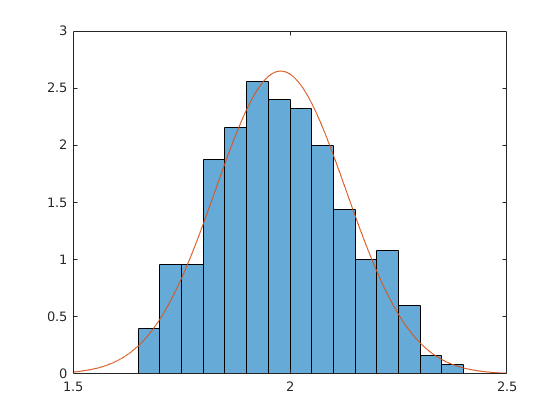

[EvalResult,Info] = sdo.evaluate(evalfcn,ps,x,Options);
z=EvalResult.out;
figure
histogram(z,'Normalization','pdf')
pd=fitdist(z,'Normal');
z1=1.5:0.01:2.5;
y=pdf(pd,z1);
hold on
plot(z1,y)

ci=paramci(pd,0.1);%0.05
ci_percent=100*(ci(:,1)-2)/2;

## ----------------------------------------------------------------------

This function computes the mean at the output.

function Vals = ComputeOutput(P,Simulator)
%DIFF_AMPL_EVALFCN
%
% Function called at each iteration of the evaluation problem.
%
% The function is called with a set of parameter values, P, and returns
% the evaluated cost, Vals.
%
% See the sdoExampleCostFunction function and sdo.evaluate for a more
% detailed description of the function signature.
%
% Simulate the model.
Simulator.Parameters = P;
Simulator = sim(Simulator);

% Retrieve logged signal data.
SimLog = find(Simulator.LoggedData,get_param('Diff_ampl1','SignalLoggingName'));
Sig_Log = find(SimLog,'Sig');

Vals.out=mean(Sig_Log.Values.Data(20:end));
end

